clear
clf
load('data/playpensample.mat')

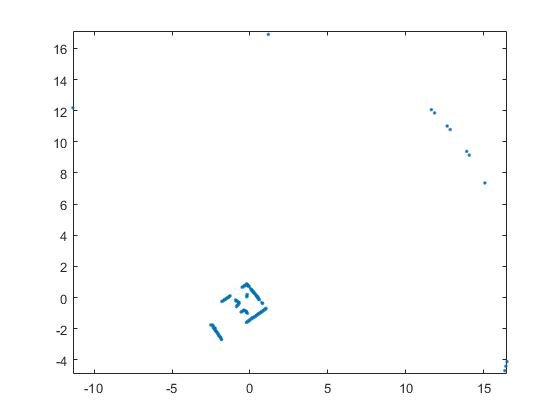

r_clean_index = find(r ~= 0);
r_clean = r(r_clean_index);
theta_clean = theta(r_clean_index);
[x, y] = pol2cart(deg2rad(theta_clean), r_clean);
points = [x y];
plot(x, y, '.')
axis equal

d = 0.01

d = 0.0100

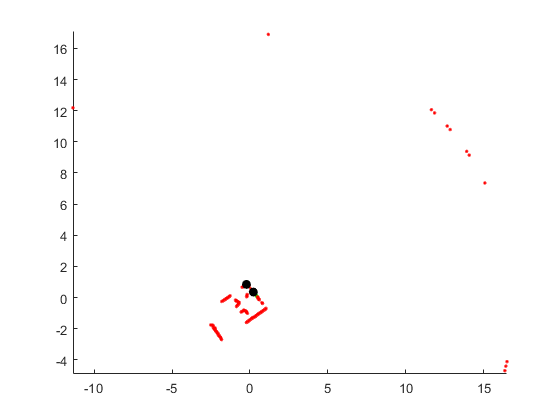

point1 = points(50, :);
point2 = points(90, :);
[inliers, outliers] = run_ransac_single(points, point1, point2, d, 1);

d = 0.01

d = 0.0100

n = 10000

n = 10000

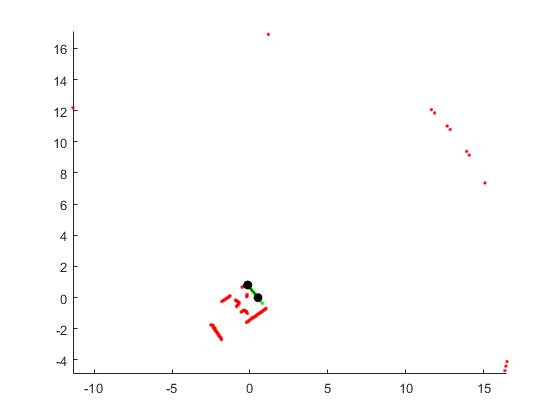

[endpoints, inliers, outliers, m, b] = ransac(points, d, n, 1);